# **Laboratorio 4**

# **Modelo Cinemátco Directo**

**Nikolai****Alexander Cáceres Penagos – Andrés Felipe Forero Salas - ****Ivan****Mauricio Hernández Triana**

Se trabaja con la versión actualizada del Robot Phantom X, teniendo en cuenta lo anterior se tomaron las medidas que permiten encontrar los parámetros DHstd para el robot. A continuación se muestra un esquema ilustrativo de su configuración.

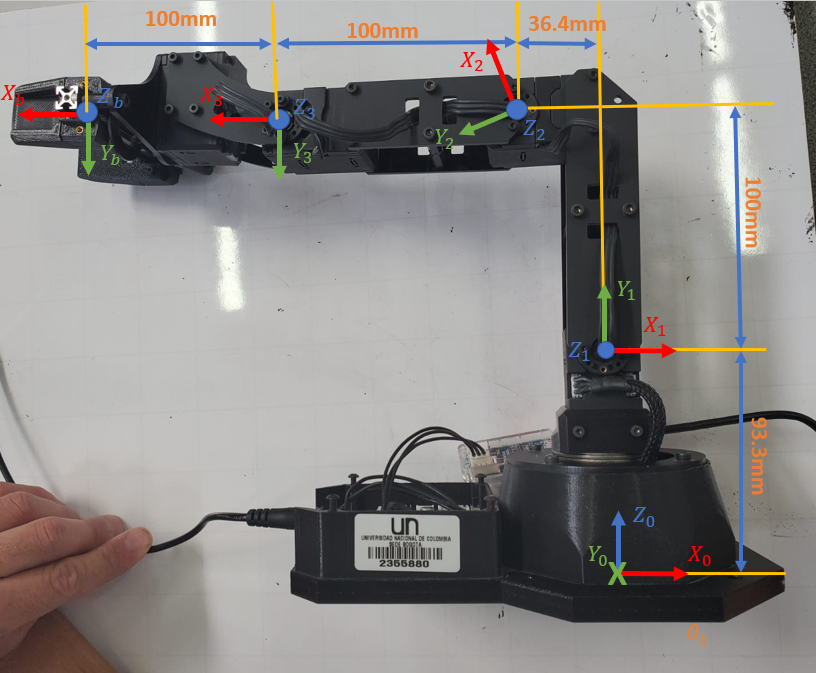

Teniendo en cuenta este diagrama, se encuentran los parámetros de articulación y eslabón para el manipulador.

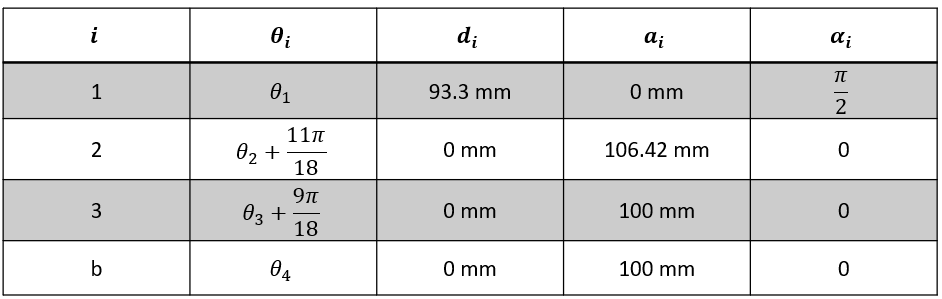

Con estos parámetros se hallan las matrices de transformación homogéneas para cada uno de los sistemas.

syms O1 O2 O3 O4
T10 = MTH(O1,93.3,0,90,2); %En radianes O1
T21 = MTH(O2+11*pi/18,0,106.42,0,2)  %En radianes O2

$$T21 = \left(\begin{array}{cccc} \cos\left(O_{2}+\frac{11\,\pi }{18}\right) & -\sin\left(O_{2}+\frac{11\,\pi }{18}\right) & 0 & \frac{5321\,\cos\left(O_{2}+\frac{11\,\pi }{18}\right)}{50}\\ \sin\left(O_{2}+\frac{11\,\pi }{18}\right) & \cos\left(O_{2}+\frac{11\,\pi }{18}\right) & 0 & \frac{5321\,\sin\left(O_{2}+\frac{11\,\pi }{18}\right)}{50}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T32 = MTH(O3+9*pi/18,0,100,0,2)  %En radianes O3

$$T32 = \left(\begin{array}{cccc} \cos\left(O_{3}+\frac{\pi }{2}\right) & -\sin\left(O_{3}+\frac{\pi }{2}\right) & 0 & 100\,\cos\left(O_{3}+\frac{\pi }{2}\right)\\ \sin\left(O_{3}+\frac{\pi }{2}\right) & \cos\left(O_{3}+\frac{\pi }{2}\right) & 0 & 100\,\sin\left(O_{3}+\frac{\pi }{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Tb3 = MTH(O4,0,100,0,2)  %En radianes O4

$$Tb3 = \left(\begin{array}{cccc} \cos\left(O_{4}\right) & -\sin\left(O_{4}\right) & 0 & 100\,\cos\left(O_{4}\right)\\ \sin\left(O_{4}\right) & \cos\left(O_{4}\right) & 0 & 100\,\sin\left(O_{4}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Finalmente se puede encontrar el modelo geométrico directo, a través del modelo interno de la cadena cinemática.

Tb0 = T10*T21*T32*Tb3

Teniendo en cuenta las configuraciones especificadas; se encuentra la posición y orientación del último sistema coordenado respecto al marco {0}. La orientación se expresa en ángulos de Euler.

qz = [0 0 0 0 0];
Tb0s0 = double(subs(Tb0,[O1 O2 O3 O4],qz(1:4)));
poses0 = [Tb0s0(1:3,4);tr2eul(Tb0s0,'deg')']

poses0 =  -224.3363
         0
  124.8981
  -90.0000
   90.0000
  -70.0000



q1 = [-20 20 -20 20 0]*(pi/180);
Tb0s1 = double(subs(Tb0,[O1 O2 O3 O4],q1(1:4)));
poses1 = [Tb0s1(1:3,4);tr2eul(Tb0s1,'deg')']

poses1 =  -224.5670
   81.7357
   76.3417
 -110.0000
   90.0000
  -50.0000



q2 = [30 -30 30 -30 0]*(pi/180);
Tb0s2 = double(subs(Tb0,[O1 O2 O3 O4],q2(1:4)));
poses2 = [Tb0s2(1:3,4);tr2eul(Tb0s2,'deg')']

poses2 =  -150.6628
  -86.9852
  181.2660
  -60.0000
   90.0000
 -100.0000



q3 = [-90 15 -55 17 0]*(pi/180);
Tb0s3= double(subs(Tb0,[O1 O2 O3 O4],q3(1:4)));
poses3 = [Tb0s3(1:3,4);tr2eul(Tb0s3,'deg')']

poses3 =          0
  254.8722
  219.9098
  180.0000
   90.0000
  -93.0000



q4 = [-90 45 -55 45 10]*(pi/180);
Tb0s4 = double(subs(Tb0,[O1 O2 O3 O4],q4(1:4)));
poses4 = [Tb0s4(1:3,4);tr2eul(Tb0s4,'deg')']

poses4 =          0
  252.2877
   38.9950
  180.0000
   90.0000
  -35.0000


Usando el Toolbox de Peter Corke

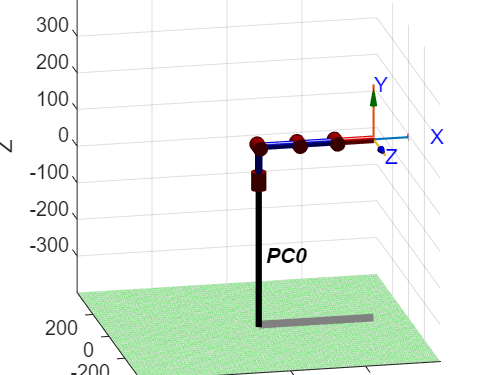

%Se crea la matriz de parámetros
DHstd = [0 93.3 0 pi/2;11*pi/18 0 106.42 0;9*pi/18 0 100 0;0 0 100 0];
r = SerialLink(DHstd);

r.name = 'PC0';
figure()
r.plot(qz(1:4))
view([-12 17])

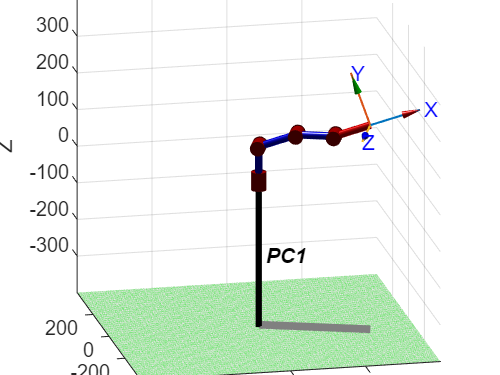

r.name = 'PC1';
figure()
cla;
r.plot(q1(1:4))
view([-12 17])

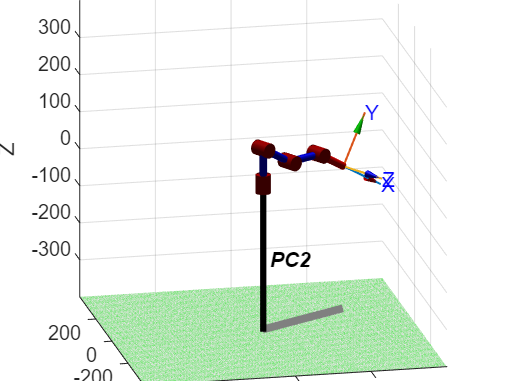

r.name = 'PC2';
figure()
cla;
r.plot(q2(1:4))
view([-12 17])

r.name = 'PC3';
figure()
cla;
r.plot(q3(1:4))
view([-12 17])

r.name = 'PC4';
figure()
cla;
r.plot(q4(1:4))
view([-12 17])